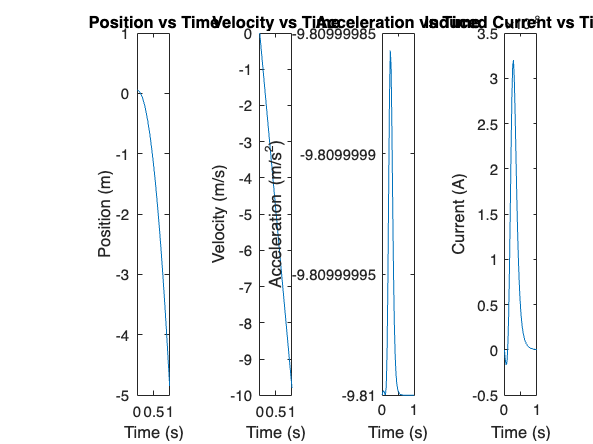

clearvars
clc
clf

% Constants
% Permeability of vacuum
mu0 = 4 * pi * 1e-7;
% Gravity
g = 9.81;
% Magnetic moment of the dipole
M = 2.5;

% Variable values
% Radius of the loop
r = 0.5;
% Number of turns
N = 30;
% Resistance
R = 0.7;
% Mass
m = 0.65;

% Constants for motion equations
km = (9 * (mu0 ^ 2) * (M ^ 2) * (r ^ 4) * (N ^ 2)) / (4 * m * R);
km2 = (3 * mu0 * M * N * (r ^ 2)) / (2 * R);

% Initial conditions
v0 = 0;
z0 = 0.05;
tt = 1;

% Acceleration function
A = @(z, v) - (km * (z.^2)./ ((r.^2 + z.^2).^5)).* v - g;

% Differential equation system dydt
dydt = @(t, y) [y(2); A(y(1), y(2))];

% ODE system of differential equations
[t, y] = ode45(dydt, [0 tt], [z0; v0]);

% Calculate position (z), velocity (v), acceleration (a), force (f), and induced current (I)
z = y(:, 1);
v = y(:, 2);
a = A(z, v);
f = m * a;
I = km .* z .* v ./ ((r * r + z .* z) .^ (2.5));

% Generate plots
subplot(1, 4, 1);
plot(t, z);
title('Position vs Time');
xlabel('Time (s)');
ylabel('Position (m)');

subplot(1, 4, 2);
plot(t, v);
title('Velocity vs Time');
xlabel('Time (s)');
ylabel('Velocity (m/s)');

subplot(1, 4, 3);
plot(t, a);
title('Acceleration vs Time');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

subplot(1, 4, 4);
plot(t, I);
title('Induced Current vs Time');
xlabel('Time (s)');
ylabel('Current (A)');